rng default;

dr = .0005;
ic = linspace(0,2*pi-1/100,1000)';
xci = cos(ic).*(.1-dr)+.5;
yci = sin(ic).*(.1-dr)+.5;
xco = cos(ic).*(.1+dr)+.5;
yco = sin(ic).*(.1+dr)+.5;


bt = .05;

r     = rand([10000,1]);
theta = rand([10000,1])*2*pi;
% x = interp1([0,1],[bt,1-bt],rand([2000,1]));
% y = interp1([0,1],[bt,1-bt],rand([2000,1]));
% x = 4.*(x-.5).^3+.5;
% y = 4.*(y-.5).^3+.5;

x = (r.*cos(theta).*.5+.5);
y = (r.*sin(theta).*.5+.5);

% rng default  % For reproducibility
% p = haltonset(2,'Skip',1e3,'Leap',1e2)
% p = scramble(p,'RR2')
% X0 = net(p,500);

validRP = ~inpolygon(x,y,xco,yco)|inpolygon(x,y,xci,yci);
x = x(validRP);
y = y(validRP);

xc = [xco;xci];
yc = [yco;yci];
dl = bt/5

dl = 0.0100

[mx,my] = meshgrid(0:dl:1,0:dl:1);
mc = mx == 0 | mx == 1 | my == 0 | my == 1;
mcmp = mx ~= 1 | my ~= 1;
[mxm,mym] = meshgrid((0:dl:(1-dl))+dl/2,(0:dl:(1-dl))+dl/2);
x = [mxm(:);mx(~mc)];
y = [mym(:);my(~mc)];
xt = [x;mx(mc)];
yt = [y;my(mc)];
DT = delaunayTriangulation([xt yt])

DT =   delaunayTriangulation with properties:

              Points: [20201×2 double]
    ConnectivityList: [40000×3 double]
         Constraints: []


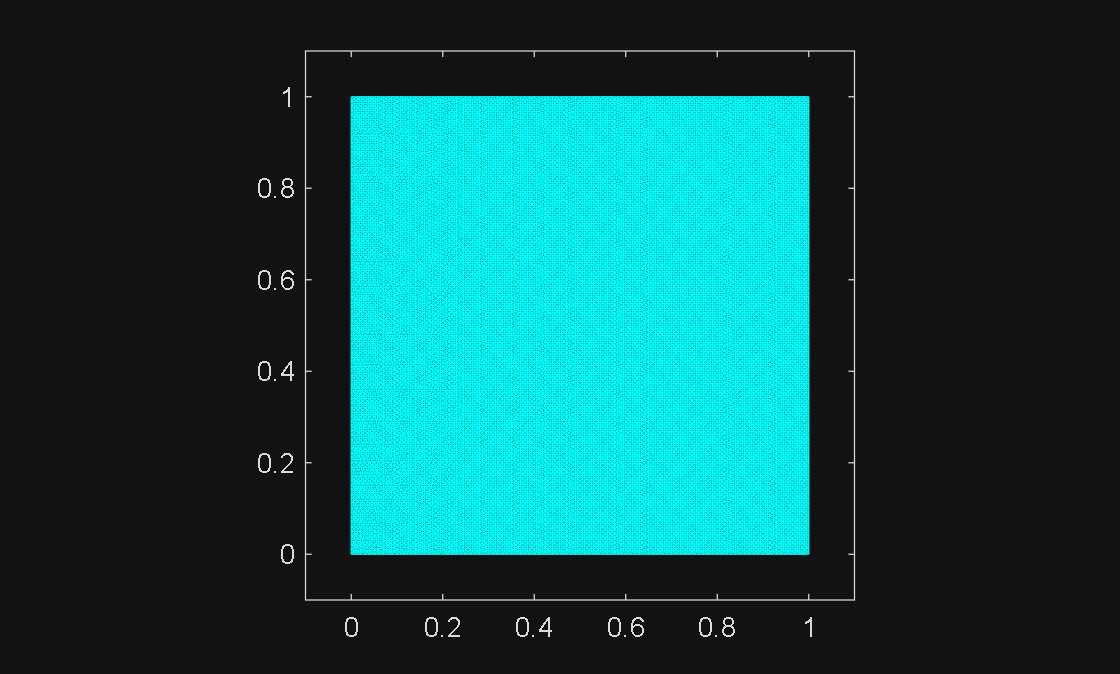

% mDT = delaunayTriangulation([mx my]');
triplot(DT,'cyan');
hold on
% triplot(mDT,mx,my);
axis square;
xlim([-.1 1.1])
ylim([-.1 1.1])